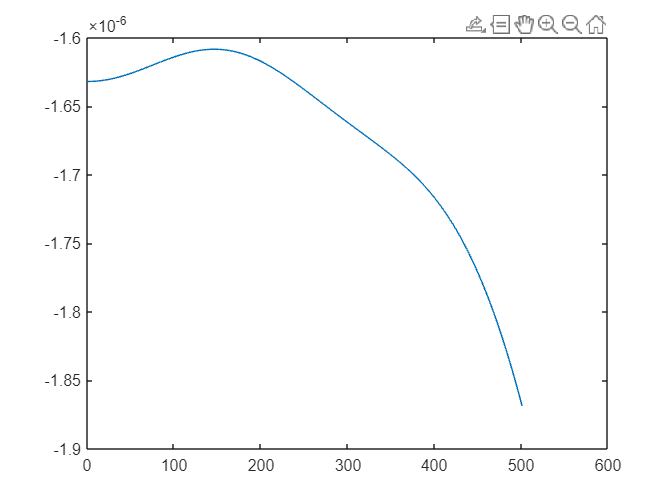

 a=1.6*10^(-6);k=9510;dt=0.01;tesx1=zeros(1,500);tesv1=zeros(1,500);tesx2=zeros(1,500);tesv2=zeros(1,500);tesx3=zeros(1,500);tesv3=zeros(1,500);
 s=0;
x=zeros(101,101);y=zeros(101,101);
for i=1:1:101
    if (mod(i,2)==0)
        for j=2:2:100
            x(i,j)=0.5*a*(j-51);
            y(i,j)=0.5*sqrt(3)*a*(51-i);

        end
    else
        for j=1:2:101
            x(i,j)=0.5*a*(j-51);
            y(i,j)=0.5*sqrt(3)*a*(51-i);
        end
    end
end

q=7280*1.6*10^(-19)*ones(101,101);vx=zeros(101,101);vy=zeros(101,101);
% q(51,51)=11200*1.6*10^(-19);
m=6.13*10^(-13)*ones(101,101);
% m(51,51)=8.03*10^(-13);
vx;vy;x;y;



x(51,49)=x(51,49)-0.02*a;
xt0=x;yt0=y;
% 以上为初始条件


%以下为迭代运算算每一时刻的速度和位移
for t=0:dt:5
    xt=x;yt=y;vxt=vx;vyt=vy;
    for i=2:1:100
        if (mod(i,2)==0)
            for j=4:2:98
 
                [x(i,j),~,~,~,~]=xlg(xt(i,j),vxt(i,j),dt);
                [y(i,j),~,~,~,~]=xlg(yt(i,j),vyt(i,j),dt);
                vx(i,j)=vxnn(xt(i,j),xt(i,j-2),xt(i+1,j-1),xt(i-1,j-1),xt(i-1,j+1),xt(i+1,j+1),xt(i,j+2),yt(i,j),yt(i,j-2),yt(i+1,j-1),yt(i-1,j-1),yt(i-1,j+1),yt(i+1,j+1),yt(i,j+2),vxt(i,j),vxt(i,j-2),vxt(i+1,j-1),vxt(i-1,j-1),vxt(i-1,j+1),vxt(i+1,j+1),vxt(i,j+2),vyt(i,j),vyt(i,j-2),vyt(i+1,j-1),vyt(i-1,j-1),vyt(i-1,j+1),vyt(i+1,j+1),vyt(i,j+2),dt,k,q(i,j),q(i,j-2),q(i+1,j-1),q(i-1,j-1),q(i-1,j+1),q(i+1,j+1),q(i,j+2),m(i,j));
                vy(i,j)=vynn(xt(i,j),xt(i,j-2),xt(i+1,j-1),xt(i-1,j-1),xt(i-1,j+1),xt(i+1,j+1),xt(i,j+2),yt(i,j),yt(i,j-2),yt(i+1,j-1),yt(i-1,j-1),yt(i-1,j+1),yt(i+1,j+1),yt(i,j+2),vxt(i,j),vxt(i,j-2),vxt(i+1,j-1),vxt(i-1,j-1),vxt(i-1,j+1),vxt(i+1,j+1),vxt(i,j+2),vyt(i,j),vyt(i,j-2),vyt(i+1,j-1),vyt(i-1,j-1),vyt(i-1,j+1),vyt(i+1,j+1),vyt(i,j+2),dt,k,q(i,j),q(i,j-2),q(i+1,j-1),q(i-1,j-1),q(i-1,j+1),q(i+1,j+1),q(i,j+2),m(i,j));
               
            end
        else
            for j=3:2:99

                [x(i,j),~,~,~,~]=xlg(xt(i,j),vxt(i,j),dt);
                [y(i,j),~,~,~,~]=xlg(yt(i,j),vyt(i,j),dt);
                vx(i,j)=vxnn(xt(i,j),xt(i,j-2),xt(i+1,j-1),xt(i-1,j-1),xt(i-1,j+1),xt(i+1,j+1),xt(i,j+2),yt(i,j),yt(i,j-2),yt(i+1,j-1),yt(i-1,j-1),yt(i-1,j+1),yt(i+1,j+1),yt(i,j+2),vxt(i,j),vxt(i,j-2),vxt(i+1,j-1),vxt(i-1,j-1),vxt(i-1,j+1),vxt(i+1,j+1),vxt(i,j+2),vyt(i,j),vyt(i,j-2),vyt(i+1,j-1),vyt(i-1,j-1),vyt(i-1,j+1),vyt(i+1,j+1),vyt(i,j+2),dt,k,q(i,j),q(i,j-2),q(i+1,j-1),q(i-1,j-1),q(i-1,j+1),q(i+1,j+1),q(i,j+2),m(i,j));
                vy(i,j)=vynn(xt(i,j),xt(i,j-2),xt(i+1,j-1),xt(i-1,j-1),xt(i-1,j+1),xt(i+1,j+1),xt(i,j+2),yt(i,j),yt(i,j-2),yt(i+1,j-1),yt(i-1,j-1),yt(i-1,j+1),yt(i+1,j+1),yt(i,j+2),vxt(i,j),vxt(i,j-2),vxt(i+1,j-1),vxt(i-1,j-1),vxt(i-1,j+1),vxt(i+1,j+1),vxt(i,j+2),vyt(i,j),vyt(i,j-2),vyt(i+1,j-1),vyt(i-1,j-1),vyt(i-1,j+1),vyt(i+1,j+1),vyt(i,j+2),dt,k,q(i,j),q(i,j-2),q(i+1,j-1),q(i-1,j-1),q(i-1,j+1),q(i+1,j+1),q(i,j+2),m(i,j));
                
            end
        end
    end


% 以下为边界条件
    for i=1:1:101
        [x(i,1),~,~,~,~]=xlg(xt(i,1),vxt(i,1),dt);
        vx(i,1)=0;
        [x(i,2),~,~,~,~]=xlg(xt(i,2),vxt(i,2),dt);
        vx(i,2)=0;
        [x(i,101),~,~,~,~]=xlg(xt(i,101),vxt(i,101),dt);
        vx(i,101)=0;
        [x(i,100),~,~,~,~]=xlg(xt(i,100),vxt(i,100),dt);
        vx(i,100)=0;
    end
    for j=3:2:99
        [x(1,j),~,~,~,~]=xlg(xt(1,j),vxt(1,j),dt);
        vx(1,j)=0;
        [x(101,j),~,~,~,~]=xlg(xt(101,j),vxt(101,j),dt);
        vx(101,j)=0;
    end


    s=s+1;
  tesx1(1,s)=x(51,49);tesv1(1,s)=vx(51,49); tesx2(1,s)=x(51,51);tesv2(1,s)=vx(51,51);tesx3(1,s)=x(50,50);tesv3(1,s)=vx(50,50);



end 


plot(tesx1)

xt1=x;yt1=y;

  %画图（很慢）
 
 % for i=1:1:101
 %    if (mod(i,2)==0)
 %        for j=2:2:100
 % 
 %            plot(xt0(i,j),yt0(i,j),'r*',xt1(i,j),yt1(i,j),'g*');
 %            line([xt0(i,j),xt1(i,j)],[yt0(i,j),yt1(i,j)],'color','red');
 %            hold on ;
 % 
 %        end
 %      else
 %        for j=1:2:101
 %            plot(xt0(i,j),yt0(i,j),'r*',xt1(i,j),yt1(i,j),'g*');
 %            line([xt0(i,j),xt1(i,j)],[yt0(i,j),yt1(i,j)],'color','red');
 %            hold on ;
 %        end
 %    end
 % end
 % axis equal 




